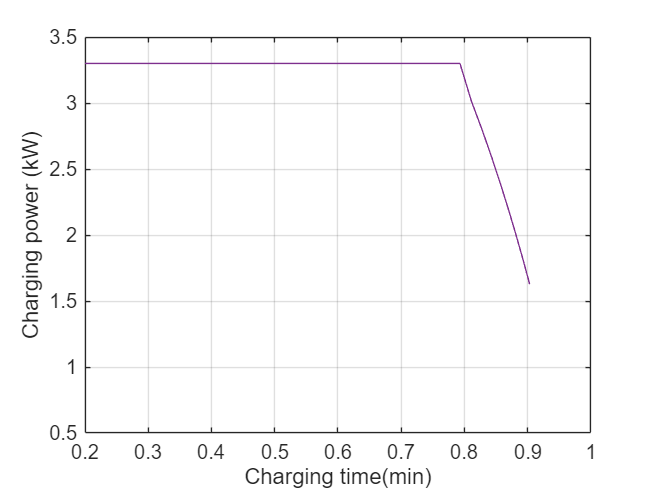

format long

% 经验参数定义
A=0.468; B=3.5294; K=0.00876;

% SOC 相关阈值
SOC_cut=0.78; % SOC 的截止值（充电模式切换点）
SOC_ce=0.9;  % SOC 的终止值（目标 SOC）

% 电池参数
C=3.3;       % 充电倍率（C-rate）
E_Ah=1;      % 电池容量 (Ah)
tau_cs=1;   % 充电开始时间
tau_e=45;    % 充电结束时间
E_0=3.7348;  % 电池开路电压 (V)
n_s=150;     % 串联电池数量
n_p=60;      % 并联电池数量
V_cut=4.16;  % 充电截止电压 (V)
R=0.07;      % 电池内阻 (Ω)

% 生成时间步
t=tau_cs:tau_e;

% 初始化变量
SOC=zeros(1,length(t));
SOC_0=0.08;   % 初始 SOC
SOC(1)=SOC_0;
P_EV=zeros(1,length(t));
V_bat=zeros(1,length(t));
I_bat=zeros(1,length(t));
V=zeros(1,length(t));
E_EV=zeros(1,length(t));

% 充电过程模拟
for i=2:length(t)
    % 计算电池开路电压
    V_bat(i)=E_0-K/SOC(i-1)+A*exp(-B*E_Ah*(1-SOC(i-1)));
    
    % 计算充电电流（恒流或恒压模式）
    if SOC(i-1) <= SOC_cut
        I_bat(i) = C * E_Ah; % 恒流充电
    else
        I_bat(i) = (n_s * V_cut - n_s * V_bat(i)) / (n_s * R); % 恒压充电
    end
    
    % 计算端电压
    V(i) = min([n_s * (V_bat(i) + R * I_bat(i)), n_s * V_cut]);
    
    % 计算充电功率 (kW)
    P_EV(i) = n_p * V(i) * I_bat(i) / 1000;
    
    % 计算 SOC 变化
    SOC(i) = SOC(i-1) + (P_EV(i) * 0.1 / V(i)) / E_Ah;
    
    % 计算累计能量 (kWh)
    E_EV(i) = n_p * E_Ah * SOC(i) * V(i) / 1000;
    
    % 终止充电条件
    if SOC(i) >= SOC_ce
        break;
    end
end
V_bat(1)=3.7348-K/SOC(1)+A*exp(-B*E_Ah*(1-SOC(1)));
I_bat(1) = C * E_Ah;
V(1) = min([n_s * (V_bat(1) + R * I_bat(1)), n_s * V_cut]);
E_EV(1) = n_p * E_Ah * SOC(1) * V(1) / 1000;
P_EV(1) = n_p * V(1) * I_bat(1) / 1000;
% 计算 SOC 变化量
deltaE_EV = E_EV(i) - E_EV(2);
deltaSOC = SOC(i) + SOC_0;

% 计算充电完成时间
tau_ce = i + tau_cs;
x=tau_cs:tau_e;
% 绘制阶梯图
hold on
y =  E_EV(tau_cs,:); % Charging power (kW)
plot(x, y, '-');
% 设置横轴范围
xlim([0,45]);

% 设置x轴刻度
xticks(0:5:45);

% 设置纵范围
ylim([0,40]);

% 设置y轴刻度
yticks(0:5:40);
% 设置网格和标签
grid on;
box on;

xlabel('Charging time(min)')
ylabel('Charging power (kW)')

hold off
saveas(gcf, 'E_EV.png');

hold on
y =  P_EV(tau_cs,:); % Charging power (kW)
plot(x, y, '-');
% 设置横轴范围
xlim([0,45]);

% 设置x轴刻度
xticks(0:5:45);

% 设置纵范围
ylim([50,150]);

% 设置y轴刻度
yticks(50:10:150);
% 设置网格和标签
grid on;
box on;

xlabel('Charging time(min)')
ylabel('Charging power (kW)')

hold off
saveas(gcf, ' P_EV.png');
x=SOC;
hold on
y =  V(tau_cs,:); % Charging power (kW)
plot(x, y, '-');
% 设置横轴范围
xlim([0.2,1]);

% 设置x轴刻度
xticks(0.2:0.1:1);

% 设置纵范围
ylim([585,625]);

% 设置y轴刻度
yticks(585:5:625);
% 设置网格和标签
grid on;
box on;

xlabel('Charging time(min)')
ylabel('Charging power (kW)')

hold off
saveas(gcf, ' V.png');
hold on
y =  I_bat(tau_cs,:); % Charging power (kW)
plot(x, y, '-');
% 设置横轴范围
xlim([0.2,1]);

% 设置x轴刻度
xticks(0.2:0.1:1);
% 设置纵范围
ylim([0.5,3.5]);

% 设置y轴刻度
yticks(0.5:0.5:3.5);
% 设置网格和标签
grid on;
box on;

xlabel('Charging time(min)')
ylabel('Charging power (kW)')

hold off
saveas(gcf, ' I.png');